# Assignment 1

clear
rng(10)
addpath('functions')


## Question 1.1

s.A = [1, -3.88098254, 5.64726905, -3.6515443, 0.88525793];
s.B = [0.4453368,-1.71110786,2.49838163, -1.64272524, 0.41012833];

% 
% % minreal tol = 0.1:
% s.A = [1	-2.93295410542636	2.86674486023263	-0.933788061325452];
% s.B = [0.445336800000000	-1.28889959687027	1.27642094733644	-0.432595129042807];
% 
% 
% % minreal tol = 0.5:
% s.A = [1	-1.94279490608771	0.943068611541607];
% s.B = [0.445336800000000	-0.846978049756568	0.435938305615007];

% Est
% s.A = [1	-0.628054600018803	-0.340780053692741	-0.123253583434919	0.0964114956017608];
% s.B = [0.154187616014832	-0.156669833035350	0.0706699303652418	0.0359340974766847	0.392677261233270];


## Question 1.2

syms y_1 y_2 y_3 y_4 u_0 u_1 u_2 u_3 u_4 
phi =  [y_1 y_2 y_3 y_4 u_0 u_1 u_2 u_3 u_4]';
theta = ([3.88098254,5.64726905,-3.6515443,0.88525793,0.4453368,-1.7110786,2.49838163,-1.64272524,0.41012833]');
vpa(phi'*theta)

$$ans = 0.44533679999999997711768173758173\,u_{0}-1.7110786000000000051102233555866\,u_{1}+2.4983816299999999088754520926159\,u_{2}-1.6427252400000000864821458890219\,u_{3}+0.41012832999999998540019419124292\,u_{4}+3.8809825400000002026956735790009\,y_{1}+5.6472690500000002344904714846052\,y_{2}-3.6515442999999998541227341775084\,y_{3}+0.88525792999999997068272250544396\,y_{4}$$

## Question 1.3

Stable with no stochastic term:

eigs = roots(s.A)

eigs =    0.9902 + 0.0000i
   0.9947 + 0.0000i
   0.9480 + 0.0005i
   0.9480 - 0.0005i


abs(eigs)

ans =     0.9902
    0.9947
    0.9480
    0.9480


## Question 1.4

data = readmatrix('Assignment1_ObservationsAndInputs.txt')';

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
s.u_data = data(:,2);
%% System Parameters
s.N = 1000;  % Number of time steps
s.sigma_e = 10^-10;  % Standard deviation of process noise
% s.sigma_e = 0.00001;
s.k = 0;  % Input delay
s.alpha = 0.01; % Gain for P ctrl
n_max = max([length(s.A),length(s.B)]);
s.u_init = zeros(n_max,1);
s.y_init = zeros(n_max,1);
s.ref = data(1:s.N,2);

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
% Stochastic(Stochastic) (True [1],  False [2])
% Control type (ctrl) (Pctrl [1], MV [2], MV0 [3], s.u_data [4], Off [5])
SP = 1;
Stochastic = 1;
ctrl = 4;
s = run_case(s, SP, Stochastic, ctrl);
y_temp = s.y;
u_temp = s.u;

%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(s.y(1:end), 'b', 'LineWidth', 1.5);
plot(data(1:s.N,1), 'r', 'LineWidth', 1.5);
hold off

hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

## Question 1.5

m = 100;
[G,S] = diophantine(s.A,1,m)

G = 1.0e+04 *

    0.0001    0.0004    0.0009    0.0018    0.0031    0.0048    0.0070    0.0097    0.0130    0.0168    0.0212    0.0263    0.0319    0.0381    0.0450    0.0524    0.0605    0.0692    0.0785    0.0883    0.0987    0.1097    0.1212    0.1333    0.1458    0.1589    0.1724    0.1863    0.2007    0.2155    0.2307    0.2463    0.2622    0.2784    0.2950    0.3118    0.3290    0.3463    0.3639    0.3818    0.3998    0.4180    0.4363    0.4548    0.4735    0.4922    0.5111    0.5300    0.5490    0.5680


S = 1.0e+04 *

    1.4028   -4.0299    3.8585   -1.2314


R = conv(s.B,G)

R = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



save('diophantine_sol.mat', 'G','S')

## Question 1.6

y_obs = data(:,1);  % First row: actual observed outputs
u_data = data(:,2);      % Second row: input values
k = s.k;
N = length(y_obs);  % Total number of observations

% Initialize predicted values
offset = numel(s.B)+max([numel(S),numel(s.B),numel(R)])+k;
y_pred = [zeros(1, offset),zeros(1, N)];  % Store predictions
y_sampl =  [zeros(offset,1);s.y];
u_sampl = [zeros(offset,1);u_data];

% Simulate predictions iteratively
for t = numel(s.B)+max([numel(S),numel(s.B),numel(R)])+k:N-numel(R) + numel(s.B) + offset
    % Predict y_{t+m} using the ARX equation
    % y_pred(t+m) = R* u_data(t+m-k+(0:numel(R)-1)) + S * s.y(t-(0:numel(S)-1));
    Rterm(t) = R* u_sampl(t+m-numel(s.B)-k-(0:numel(R)-1));
    Sterm(t) = S * y_sampl(t-(0:numel(S)-1));
    y_pred(t+m-offset) =  Rterm(t) + Sterm(t);
end

y_pred = y_pred(1:end-1-offset)';

% Compute Mean Absolute Error (MAE)
MAE = mean(abs(y_pred(m+1:end) - s.y(m+1:end)));

% Display result
fprintf('Mean Absolute Error (MAE): %.5f\n', MAE);

Mean Absolute Error (MAE): 0.00001



sys_original = idpoly(s.A,s.B,'nk',1,'InputDelay',max([length(s.A), length(s.B)]));
data_arx = sim(sys_original,u_data);
figure
yp = predict(sys_original,[y_obs,u_data],m);


%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(s.y(1:end), 'b', 'LineWidth', 1.5);
% plot(data_arx(1:end), 'g--', 'LineWidth', 1.5);
% 
plot(data(1:end-1,1), 'r', 'LineWidth', 1.5);
% plot(yp(1:end)', 's', 'LineWidth', 1.5);
plot(y_pred, 'g--', 'LineWidth', 1.5);


hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

## Question 1.7

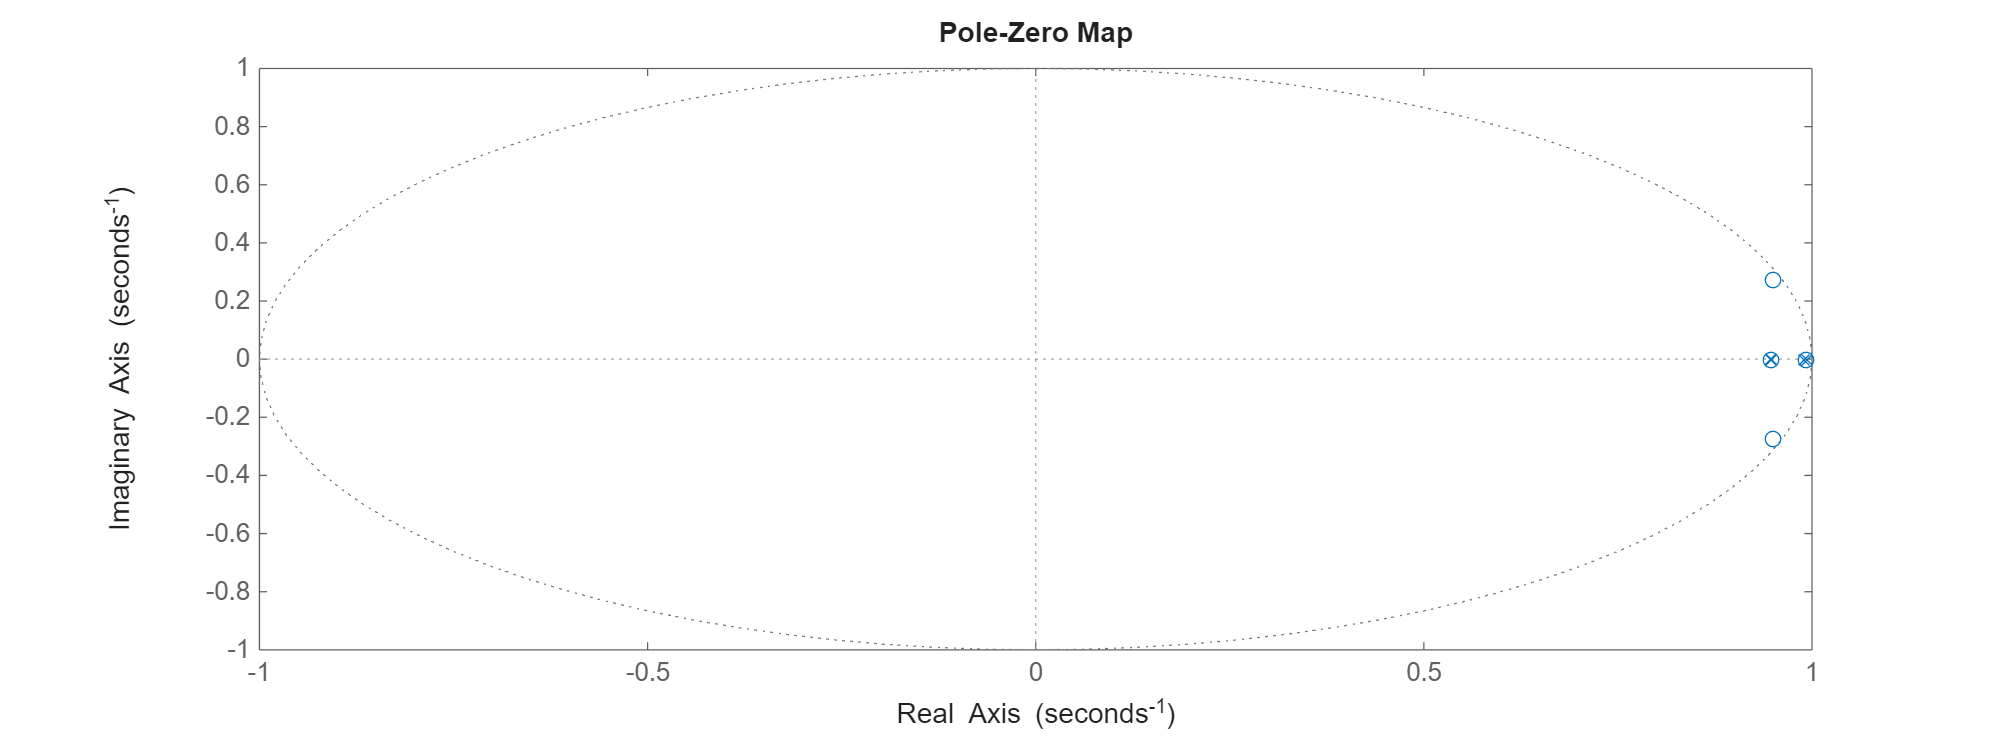

data = readmatrix('Assignment1_ObservationsAndInputs.txt')';s.u_data = data(:,2);
% s.u_data = data(:,2);
%% System Parameters
s.N = 300;  % Number of time steps
s.sigma_e = 10^-10;  % Standard deviation of process noise
s.k = 1;  % Input delay
s.alpha = 0.5; % Gain for P ctrl
n_max = max([length(s.A),length(s.B)]);
s.u_init = zeros(n_max,1);
s.y_init = zeros(n_max,1);
s.ref =  [ones(100,1);zeros(100,1);0.5*ones(100,1)];
s.u_data = s.ref;

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
% Stochastic(Stochastic) (True [1],  False [2])
% Control type (ctrl) (Pctrl [1], MV [2], MV0 [3], u_data(:,2) [4], Off [5])
SP = 4;
Stochastic = 1;
ctrl = 3;
s = run_case(s, SP, Stochastic, ctrl);

%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];

%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,2,1);
plot(s.y, 'b', 'LineWidth', 1.5);
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,2,2);
plot(s.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;
subplot(2,2,3)
plot(s.omega, 'b', 'LineWidth', 1.5);
title('Ref \omega');
% ylim([-max(omega)*1.2,max(omega)*1.2])
xlabel('Time Step');
ylabel('\omega');
grid on;
subplot(2,2,4)
plot(s.omega-s.y, 'r', 'LineWidth', 1.5);
title('Error');
xlabel('Time Step');
ylabel('error');
grid on;

## Question 1.8

% Construct the regression matrix Phi_t
% y_obs = y_temp;
y_obs = data(1:1000,1);
u_data = u_temp;
N = length(y_temp);
na = numel(s.A) -1;
nb = numel(s.B) -1;
na = 2;
nb = 2;

% Phi = zeros(N-max([na+1,nb+1]), 9);
% Y = (max([numel(s.A),numel(s.B)])+1:N);  % Output from t=3 onwards

% for t = max([na+1,nb+1])+1:N
%     Phi(t, :) = [-y_obs(t-1),-y_obs(t-2), -y_obs(t-3),-y_obs(t-4),u_data(t-s.k),u_data(t-1-s.k), u_data(t-2-s.k), u_data(t-3-s.k),u_data(t-4-s.k)];
% end

% Phi = zeros(N,numel(s.A)-1+ numel(s.B)-1+1);
% k = find(s.B, 1); % Find the first nonzero index
% 
% 
k = 0

k = 0

Phi = zeros(N,na+ nb+1);
for t = max(na,nb)+2+k: N
    Phi(t,:) = [-y_obs(t-(1:na))', u_data(t-k:-1:t-k-nb)']; %remember the sign sincee we are moviang y_t-n to right side
end

% k = 1
% Phi = zeros(N,numel(s.A)-1+ numel(s.B)-k);

%implmenting phi routine   here [y_t-1,y_t-2,u_t-1,u_t-2] 
% for t = max(numel(s.A),numel(s.B))+1: N
%     Phi(t,:) = [-y_obs(t-(1:numel(s.A)-1))', u_data(t-(1:numel(s.B)-1+1))'];%remember the sign sincee we are moviang y_t-n to right side
% end


% Solve for estimated parameters using least squares
theta_hat = (Phi' * Phi) \ (Phi' * y_obs);
% theta_hat = pinv(Phi)*y_obs
% theta_hat = (Phi' * Phi)^-1 * (Phi' * y_obs);
% theta_hat = inv(phi'*phi)*phi'*y' 


% Display estimated vs true parameters


% disp('Estimated Parameters:');
s.A

ans =     1.0000   -3.8810    5.6473   -3.6515    0.8853


s.B

ans =     0.4453   -1.7111    2.4984   -1.6427    0.4101


A_est = [1,theta_hat(1:na)']

A_est =     1.0000   -0.6879   -0.3083


B_est = theta_hat(na+1:numel(Phi(1,:)))'

B_est =     0.0277    0.0900    0.3220


% s.A - A_est
% s.B - B_est

s.A = A_est;
s.B = B_est;

% Compute estimated parameter covariance matrix
sigma_sq_hat = var(y_obs - Phi * theta_hat);  % Residual variance
cov_theta = sigma_sq_hat * inv(Phi' * Phi);  % Theoretical covariance

disp('Estimated Variance of Parameters:');

Estimated Variance of Parameters:


% disp(diag(cov_theta));  % Display variance of each parameter

% Compare with theoretical variance
theoretical_variance = s.sigma_e^2 * inv(Phi' * Phi);
disp('Theoretical Variance of Parameters:');

Theoretical Variance of Parameters:


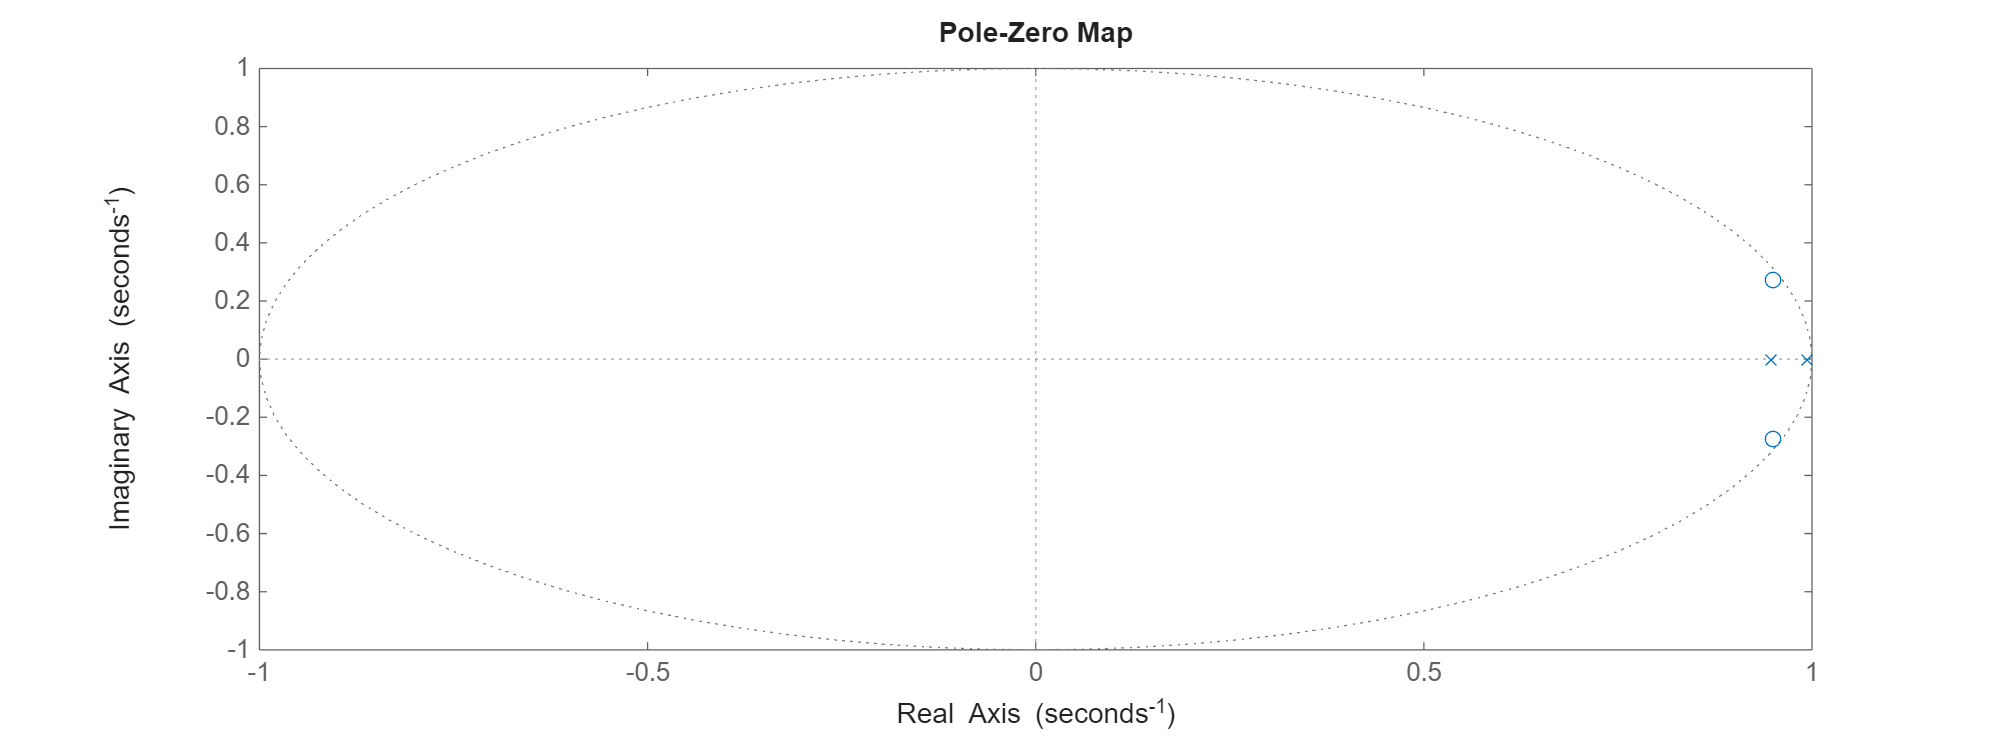

% disp(diag(theoretical_variance));


data = readmatrix('Assignment1_ObservationsAndInputs.txt')';

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
s.u_data = data(:,2);
%% System Parameters
s.N = 1000;  % Number of time steps
s.sigma_e = 10^-10;  % Standard deviation of process noise
% s.sigma_e = 0.00001;
s.k = 0;  % Input delay
s.alpha = 0.01; % Gain for P ctrl
n_max = max([length(s.A),length(s.B)]);
s.u_init = zeros(n_max,1);
s.y_init = zeros(n_max,1);
% s.ref = data(1:s.N,2);


% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
% Stochastic(Stochastic) (True [1],  False [2])
% Control type (ctrl) (Pctrl [1], MV [2], MV0 [3], s.u_data [4], Off [5])
SP = 1;
Stochastic = 1;
ctrl = 4;
s = run_case(s, SP, Stochastic, ctrl);


%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(y_obs(1:end), 'r', 'LineWidth', 1.5);
plot(s.y(1:end), 'b--', 'LineWidth', 1.5);
hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;



m = 100;
[G,S] = diophantine(s.A,1,m)

G =     1.0000    0.6879    0.7815    0.7497    0.7567    0.7517    0.7504    0.7480    0.7459    0.7437    0.7416    0.7395    0.7373    0.7352    0.7331    0.7310    0.7289    0.7268    0.7247    0.7226    0.7205    0.7185    0.7164    0.7143    0.7123    0.7102    0.7082    0.7061    0.7041    0.7021    0.7000    0.6980    0.6960    0.6940    0.6920    0.6900    0.6880    0.6861    0.6841    0.6821    0.6801    0.6782    0.6762    0.6743    0.6723    0.6704    0.6685    0.6666    0.6646    0.6627


S =     0.5721    0.1769


R = conv(s.B,G)

R =     0.0277    0.1091    0.4055    0.3126    0.3401    0.3303    0.3321    0.3303    0.3296    0.3286    0.3276    0.3267    0.3257    0.3248    0.3239    0.3229    0.3220    0.3211    0.3202    0.3192    0.3183    0.3174    0.3165    0.3156    0.3147    0.3138    0.3129    0.3120    0.3111    0.3102    0.3093    0.3084    0.3075    0.3066    0.3057    0.3048    0.3040    0.3031    0.3022    0.3013    0.3005    0.2996    0.2988    0.2979    0.2970    0.2962    0.2953    0.2945    0.2936    0.2928


## Question 1.6

y_obs = data(:,1);  % First row: actual observed outputs
u_data = data(:,2);      % Second row: input values
k = s.k;
N = length(y_obs);  % Total number of observations

% Initialize predicted values
offset = numel(s.B)+max([numel(S),numel(s.B),numel(R)])+k;
y_pred = [zeros(1, offset),zeros(1, N)];  % Store predictions
y_sampl =  [zeros(offset,1);y_obs];
u_sampl = [zeros(offset,1);u_data];

% Simulate predictions iteratively
for t = numel(s.B)+max([numel(S),numel(s.B),numel(R)])+k:N-numel(R) + numel(s.B) + offset
    % Predict y_{t+m} using the ARX equation
    % y_pred(t+m) = R* u_data(t+m-k+(0:numel(R)-1)) + S * s.y(t-(0:numel(S)-1));
    Rterm(t) = R* u_sampl(t+m-numel(s.B)-k-(0:numel(R)-1));
    Sterm(t) = S * y_sampl(t-(0:numel(S)-1));
    y_pred(t+m-offset) =  Rterm(t) + Sterm(t);
end
y_pred = y_pred(1:end-1-offset)';

% Compute Mean Absolute Error (MAE)
MAE = mean(abs(y_pred(m+1:end) - s.y(m+1:end)));

% Display result
fprintf('Mean Absolute Error (MAE): %.5f\n', MAE);

Mean Absolute Error (MAE): 5.26124


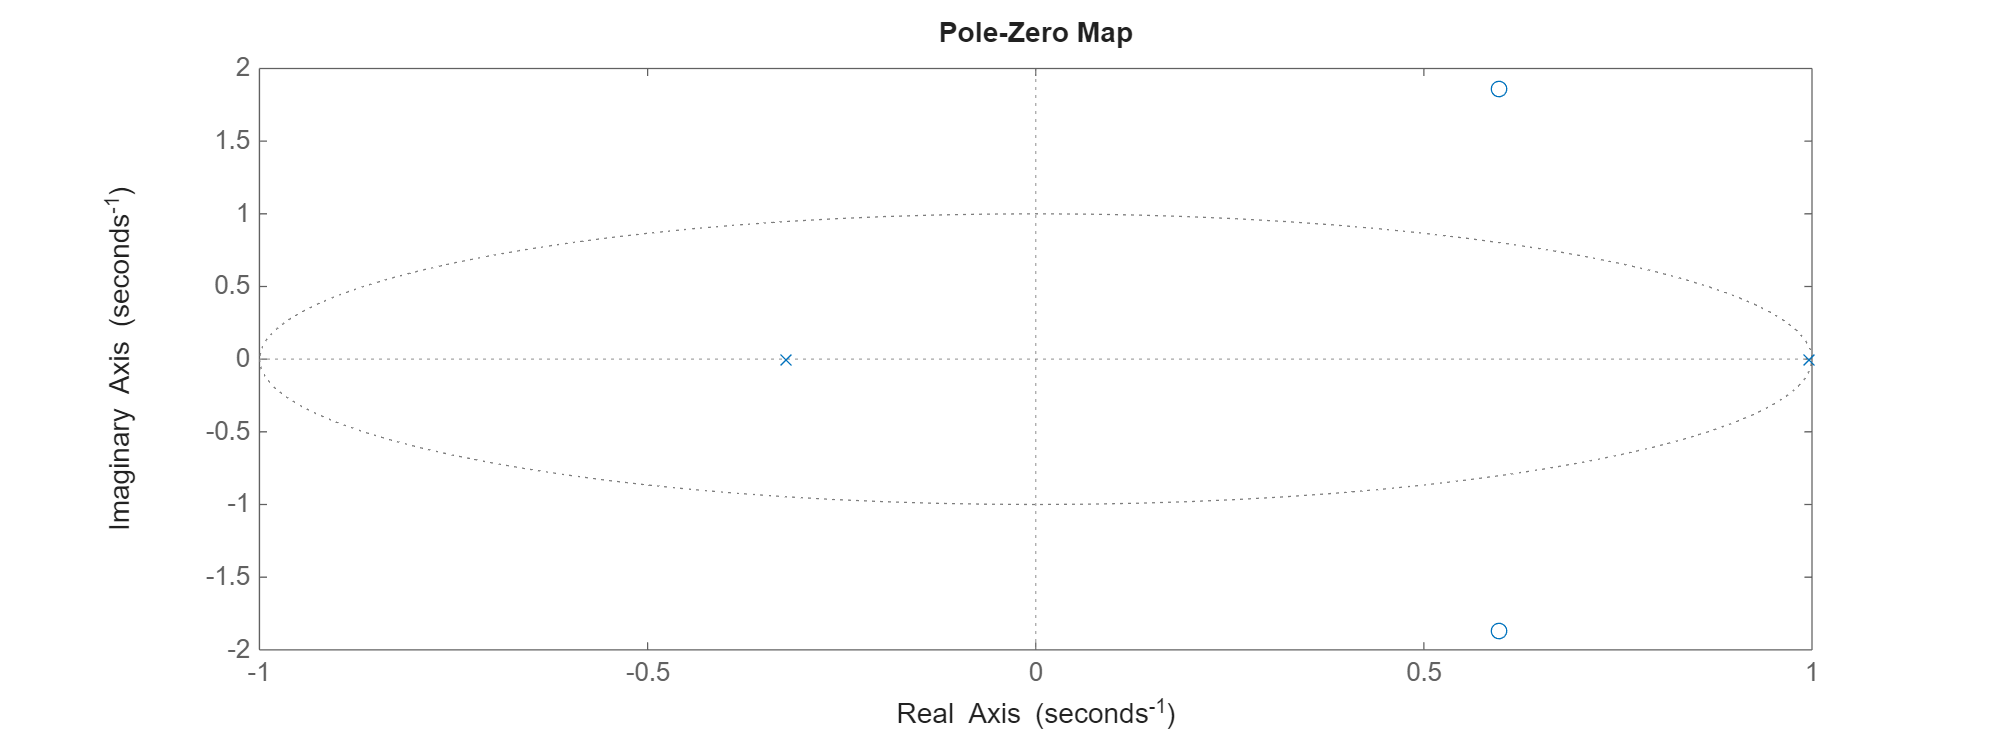


sys_original = idpoly(s.A,s.B,'nk',1,'InputDelay',max([length(s.A), length(s.B)]));
data_arx = sim(sys_original,u_data);
figure
yp = predict(sys_original,[y_obs(1:s.N),u_data(1:s.N)],m);


%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(s.y(1:end), 'b', 'LineWidth', 1.5);
% plot(data_arx(1:end), 'g--', 'LineWidth', 1.5);
plot(data(1:end-1,1), 'r', 'LineWidth', 1.5);
plot(yp(1:end)', 's', 'LineWidth', 1.5);
plot(y_pred, 'g--', 'LineWidth', 1.5);


hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

### PZ cancellation

s.A = [1, -3.88098254, 5.64726905, -3.6515443, 0.88525793];
s.B = [0.4453368,-1.71110786,2.49838163, -1.64272524, 0.41012833];

sys_original = tf(s.B, s.A,1)


sys_original =
 
  0.4453 z^4 - 1.711 z^3 + 2.498 z^2 - 1.643 z + 0.4101
  -----------------------------------------------------
     z^4 - 3.881 z^3 + 5.647 z^2 - 3.652 z + 0.8853
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


sys_est = tf(B_est, A_est,1)


sys_est =
 
  0.02771 z^2 + 0.09 z + 0.322
  ----------------------------
    z^2 - 0.6879 z - 0.3083
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


msys = minreal(sys_original,0.5)


msys =
 
  0.4453 z^2 - 0.847 z + 0.4359
  -----------------------------
     z^2 - 1.943 z + 0.9431
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


figure
pzplot(sys_original);
figure
pzplot(msys);
figure
pzplot(sys_est);
Bm = msys.Numerator{1};
Am = msys.Denominator{1};
sys_minreal = idpoly(Am,Bm,'nk',1,'InputDelay',max([length(s.A), length(s.B)]));
data_arx = sim(sys_minreal,u_data);


%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(data_arx, 'g', 'LineWidth', 1.5);
plot(y_temp', 'b--', 'LineWidth', 1.5);
plot(data(:,1), 'r', 'LineWidth', 1.5);
hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(data(:,2), 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;


## Question 1.9

s.A = [1, -3.88098254, 5.64726905, -3.6515443, 0.88525793];
s.B = [0.4453368,-1.71110786,2.49838163, -1.64272524, 0.41012833];
y_obs = y_obs(1:1000);
u_data = u_temp;
num = 9

num = 9

% Initialize Recursive Least Squares (RLS) Parameters
theta_rls = zeros(9, N); % Store estimated parameters over time
P = 100 * eye(9); % Initial covariance (high uncertainty)
lambda = 0.999; % Forgetting factor
theta_hat = zeros(9, 1); % Initial parameter estimates

% Recursive Estimation
for t = max([na+1,nb+1])+1:N
    % Regression vector Phi_t
    % Phi_t = [-y_obs(t-1),-y_obs(t-2), -y_obs(t-3),-y_obs(t-4),u_data(t-s.k),u_data(t-1-s.k), u_data(t-2-s.k), u_data(t-3-s.k),u_data(t-4-s.k)];
    Phi_t = [-y_obs(t-1),-y_obs(t-2), -y_obs(t-3),-y_obs(t-4),u_data(t-s.k),u_data(t-1-s.k), u_data(t-2-s.k), u_data(t-3-s.k),u_data(t-4-s.k)]';
    
    % Kalman gain
    K_t = P * Phi_t / (lambda + Phi_t' * P * Phi_t);
    
    % Prediction error
    e_t = y_obs(t) - Phi_t' * theta_hat;
    
    % Parameter update
    theta_hat = theta_hat + K_t * e_t;
    
    % Covariance update
    P = (P - K_t * Phi_t' * P) / lambda;
    
    % Store estimates over time
    theta_rls(:, t) = theta_hat;
end

Array indices must be positive integers or logical values.


% Plot parameter evolution
figure;
subplot(2,2,1); plot(theta_rls(1,:), 'LineWidth', 1.5); title('Estimate of a1'); xlabel('Time'); ylabel('a1');
subplot(2,2,2); plot(theta_rls(2,:), 'LineWidth', 1.5); title('Estimate of a2'); xlabel('Time'); ylabel('a2');
subplot(2,2,3); plot(theta_rls(3,:), 'LineWidth', 1.5); title('Estimate of b1'); xlabel('Time'); ylabel('a3');
subplot(2,2,4); plot(theta_rls(4,:), 'LineWidth', 1.5); title('Estimate of b2'); xlabel('Time'); ylabel('a4');

% Display final estimated parameters
disp('Final Estimated Parameters (Recursive LS):');
disp(theta_hat);



A_est = theta_hat(1:4)'
B_est = theta_hat(5:9)'
s.A = [1,A_est];
s.B = B_est;

% Compute estimated parameter covariance matrix
sigma_sq_hat = var(y_obs - Phi * theta_hat);  % Residual variance
cov_theta = sigma_sq_hat * inv(Phi' * Phi);  % Theoretical covariance

disp('Estimated Variance of Parameters:');
% disp(diag(cov_theta));  % Display variance of each parameter

% Compare with theoretical variance
theoretical_variance = s.sigma_e^2 * inv(Phi' * Phi);
disp('Theoretical Variance of Parameters:');
% disp(diag(theoretical_variance));


data = readmatrix('Assignment1_ObservationsAndInputs.txt')';

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
s.u_data = data(:,2);
%% System Parameters
s.N = 1000;  % Number of time steps
s.sigma_e = 10^-10;  % Standard deviation of process noise
% s.sigma_e = 0.00001;
s.k = 1;  % Input delay
s.alpha = 0.01; % Gain for P ctrl
n_max = max([length(s.A),length(s.B)]);
s.u_init = zeros(n_max,1);
s.y_init = zeros(n_max,1);
s.ref = data(1:s.N,2);

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
% Stochastic(Stochastic) (True [1],  False [2])
% Control type (ctrl) (Pctrl [1], MV [2], MV0 [3], s.u_data [4], Off [5])
SP = 1;
Stochastic = 1;
ctrl = 4;
s = run_case(s, SP, Stochastic, ctrl);


%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(y_obs(1:end), 'r', 'LineWidth', 1.5);
plot(s.y(1:end), 'b', 'LineWidth', 1.5);
hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;




